## Generate train and test set

clear;

train_x = [-1.6:0.05:1.6];
train_y = 1.2 * sin(pi*train_x) - cos(2.4*pi*train_x);

test_x = [-1.6:0.01:1.6];
test_y = 1.2 * sin(pi*test_x) - cos(2.4*pi*test_x);

## a. Train with sequential mode

train_x_size = size(train_x);
train_num = train_x_size(2);

% for sequential mode
train_x_cell = num2cell(train_x);
train_y_cell = num2cell(train_y);

epochs = 200;

**When hidden_size n = [1, ..., 6]**

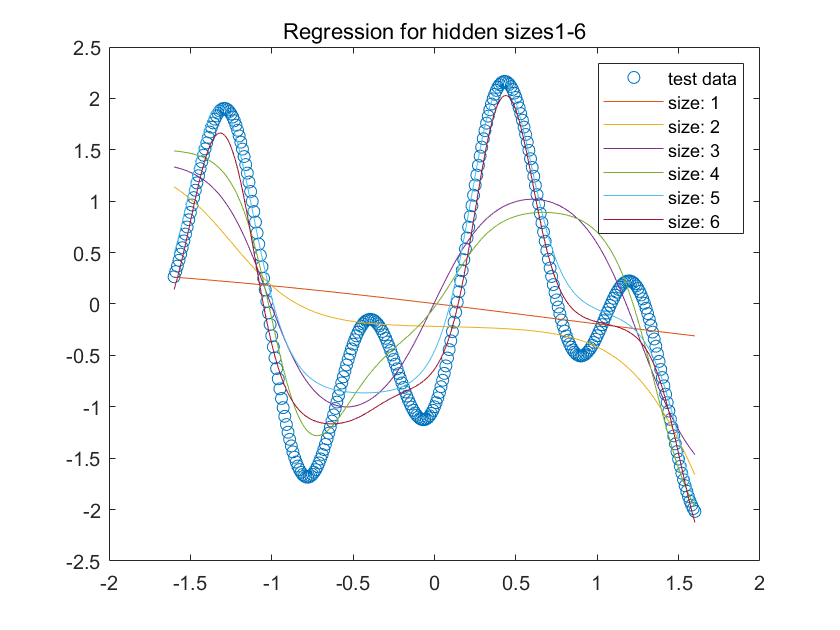

The average error in test set after100 epochs for each hidden size from1to6
    0.9047    0.7865    0.6149    0.5481    0.3125    0.2807

The average error in -3, 3 after100 epochs for each hidden size:
    0.8771    2.6714    1.6342    1.9667    2.4690    2.4660



sq_train(train_x_cell, train_y_cell, test_x, test_y, train_num, [1:1:6], 100)

**When hidden_size = [7, 8,  9, 10]**

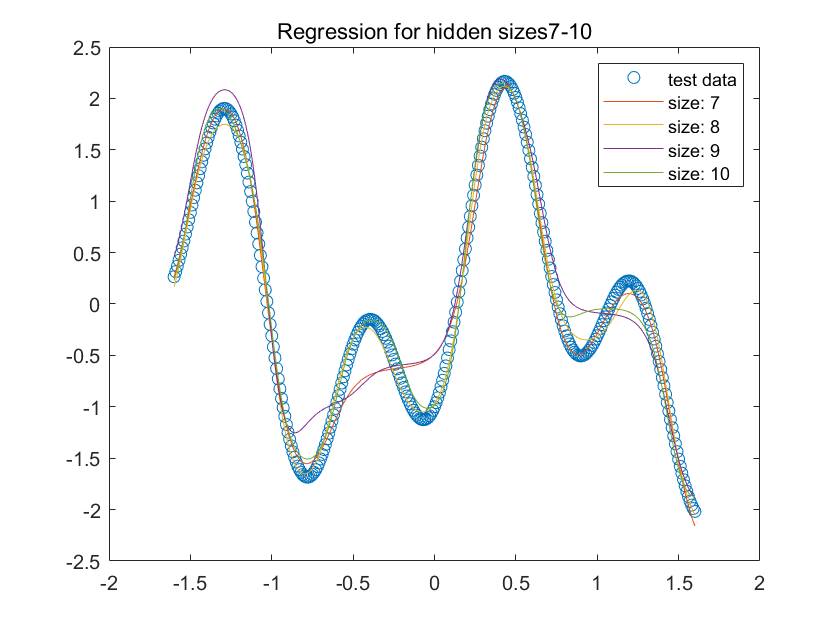

The average error in test set after100 epochs for each hidden size from7to10
    0.1350    0.0764    0.2533    0.1198

The average error in -3, 3 after100 epochs for each hidden size:
    2.2104    2.1300    1.6753    1.3757



sq_train(train_x_cell, train_y_cell, test_x, test_y, train_num, [7:1:10], 100)

**When hidden_size = [20,  50, 100]**

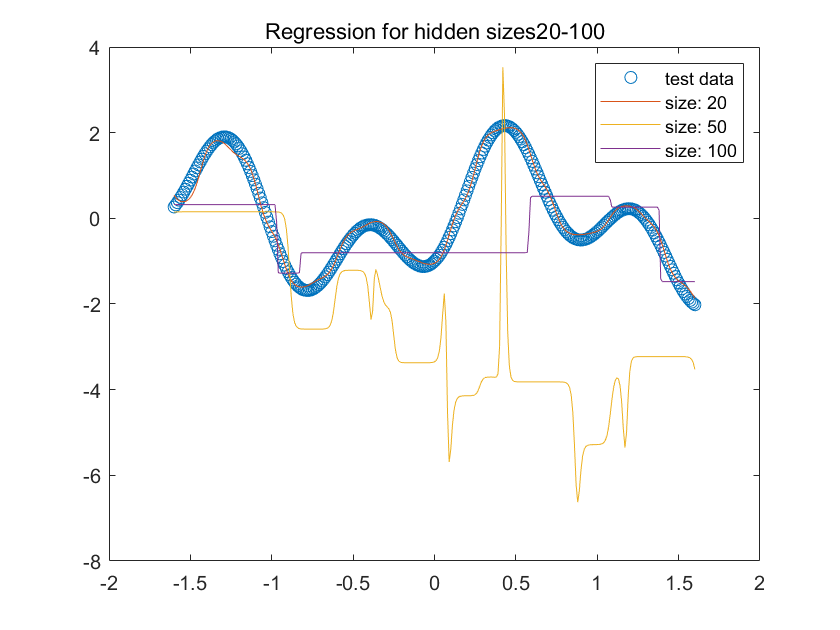

The average error in test set after100 epochs for each hidden size from20to100
    0.0904    2.6360    0.7876

The average error in -3, 3 after100 epochs for each hidden size:
    2.0298  342.7017  122.3165



sq_train(train_x_cell, train_y_cell, test_x, test_y, train_num, [20, 50, 100], 100)

## b. Batch mode with trainlm

function sq_train(x, y, test_x, test_y, train_num, hidden_sizes, epochs)
figure;
plot(test_x, test_y, 'o', 'DisplayName', 'test data');
hold on;

avg_err = zeros(size(hidden_sizes));
avg_err_o = zeros(size(hidden_sizes));

err_idx = 0;
for hidden_size = hidden_sizes
    err_idx = err_idx + 1;
    
    % one layer
    net = feedforwardnet(hidden_size);
    for epoch = 1:epochs
        idx = randperm(train_num); % shuffle the input
        net = adapt(net, x(:, idx), y(:, idx));
    end
    
    output = net(test_x);
    avg_err(err_idx) = mean(abs(output - test_y));
    
    % compute the values outside the x domain
    x_o = [-3, 3];
    y_o = 1.2 * sin(pi*x_o) - cos(2.4*pi*x_o);
    output_o = net(x_o);
    avg_err_o(err_idx) = mean(abs(output_o - y_o));
    
    plot(test_x, output, 'DisplayName', sprintf('size: %d', hidden_size));
    hold on;
end

title(strcat('Regression for hidden sizes ', num2str(hidden_sizes(1)), '-', num2str(hidden_sizes(err_idx))));
legend;

disp(strcat('The average error in test set after ', num2str(epochs), ' epochs for each hidden size from ', num2str(hidden_sizes(1)), 'to', num2str(hidden_sizes(err_idx))));
disp(avg_err);

disp(strcat('The average error in -3, 3 after ', num2str(epochs), ' epochs for each hidden size:'));
disp(avg_err_o);

end